baseline_plate_mag = 14.4688

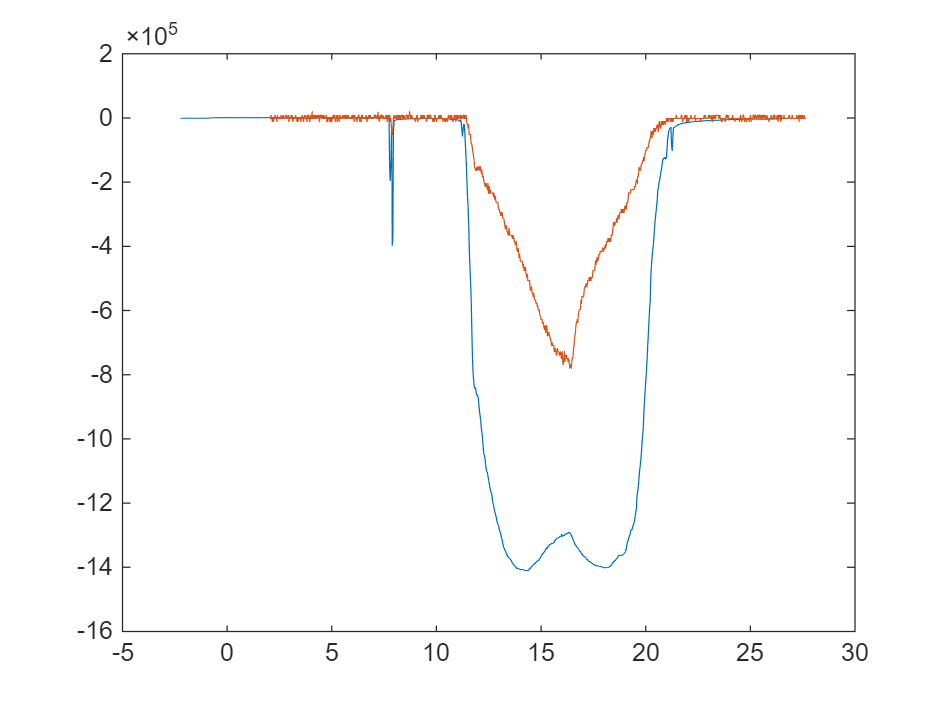

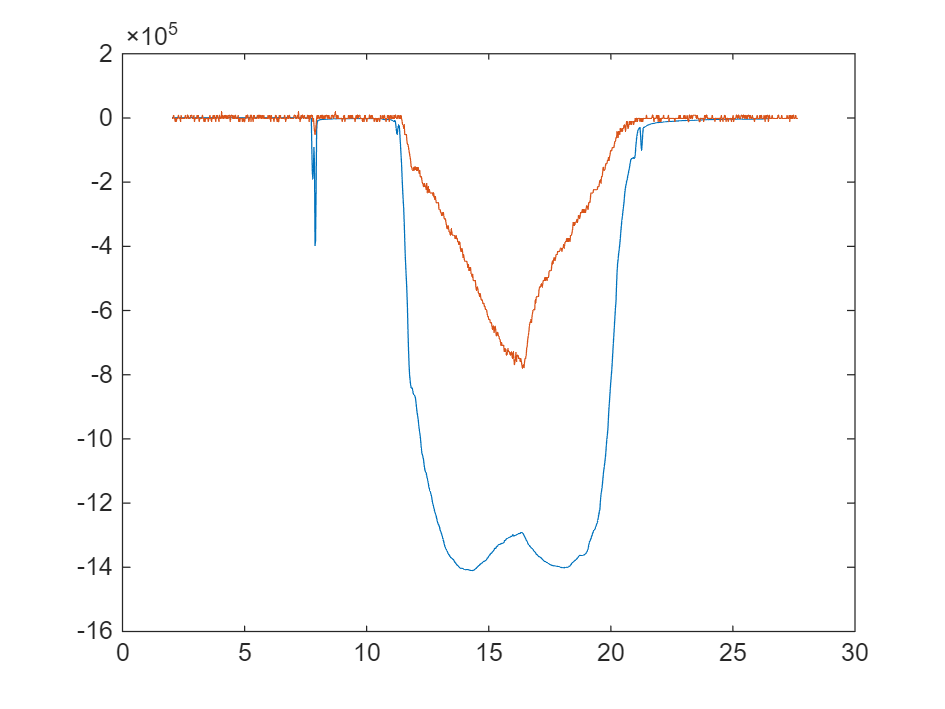

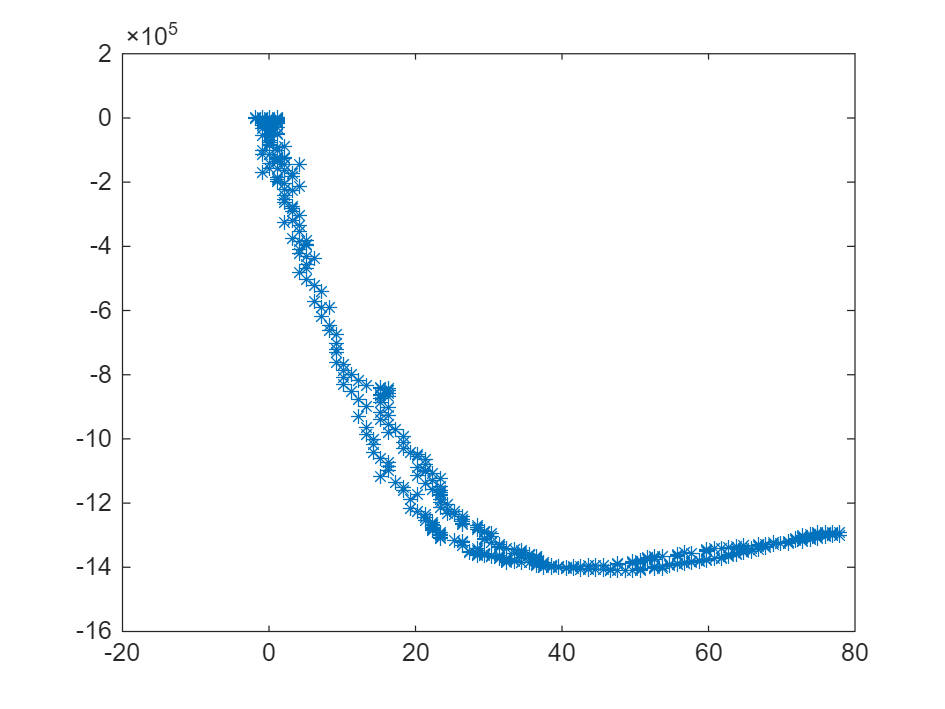

max_force = 49.6512

baseline_plate_mag = 14.3173

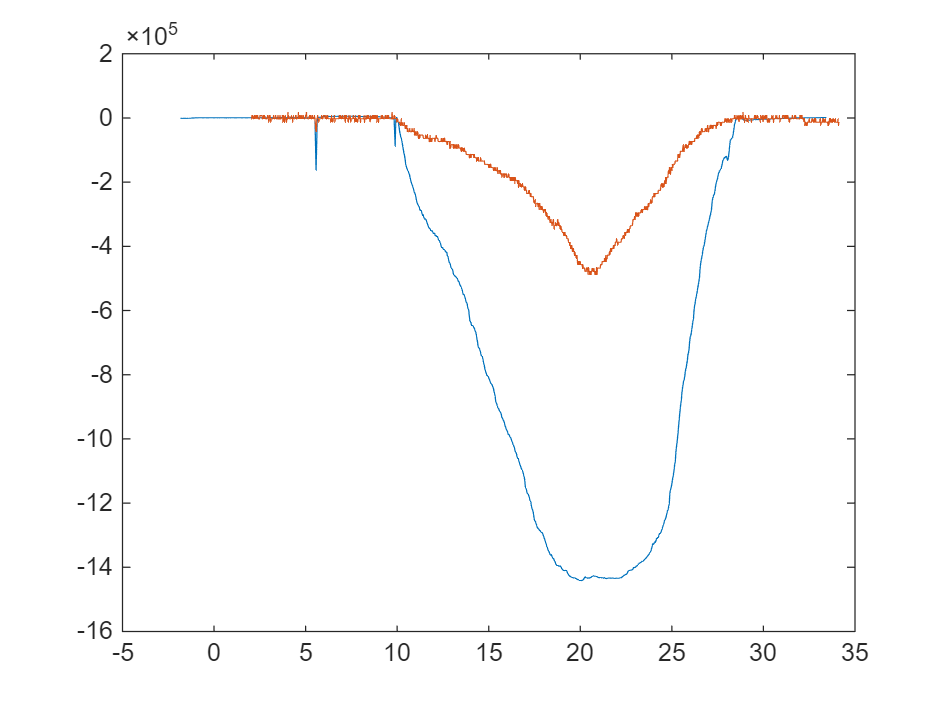

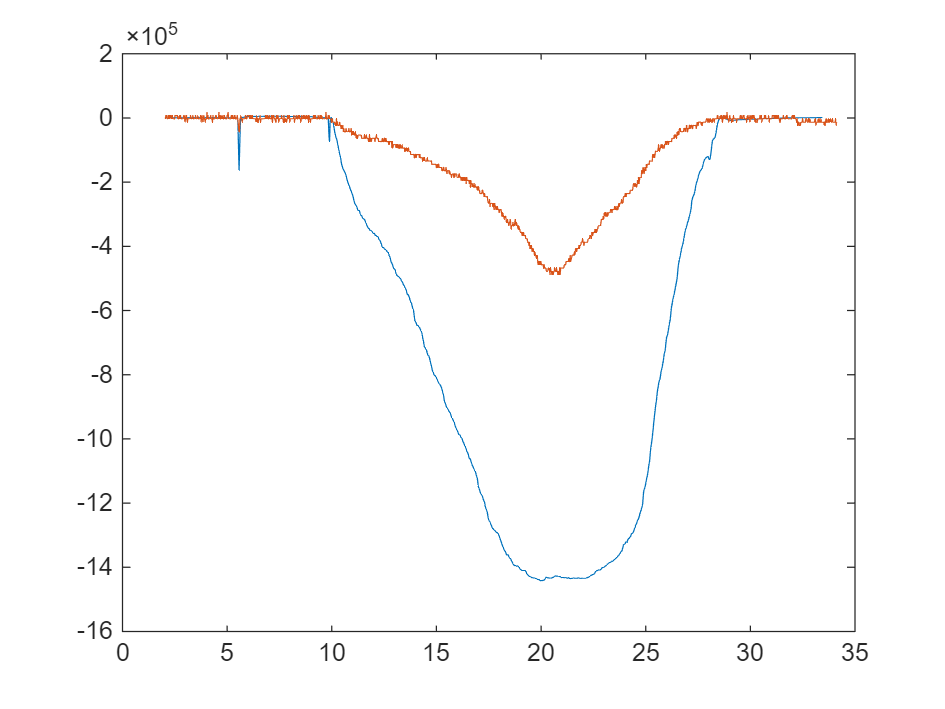

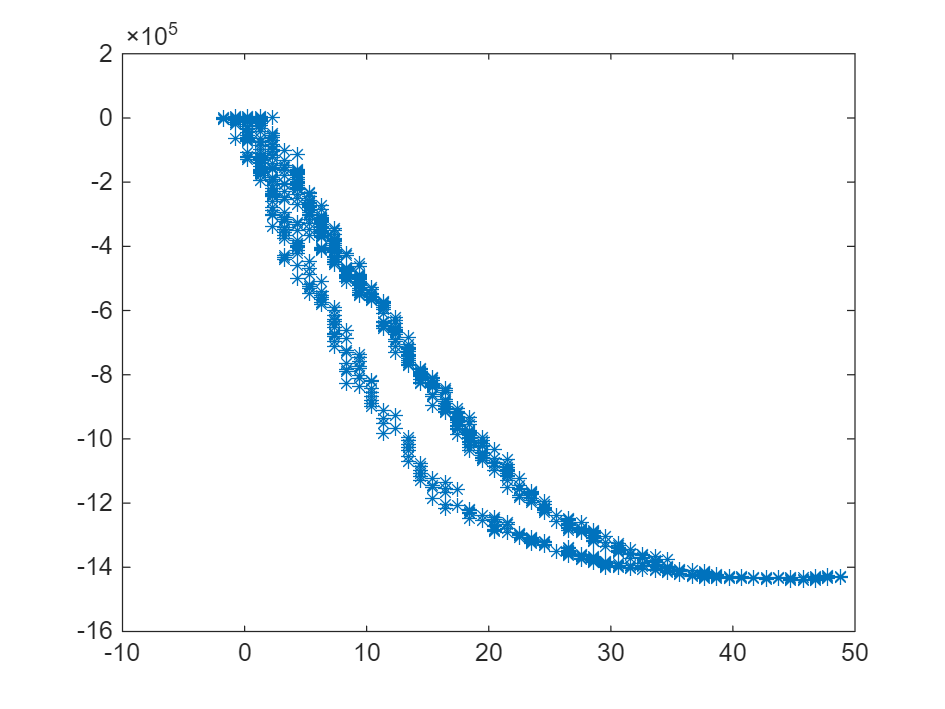

max_force = 44.7427

baseline_plate_mag = 14.6809

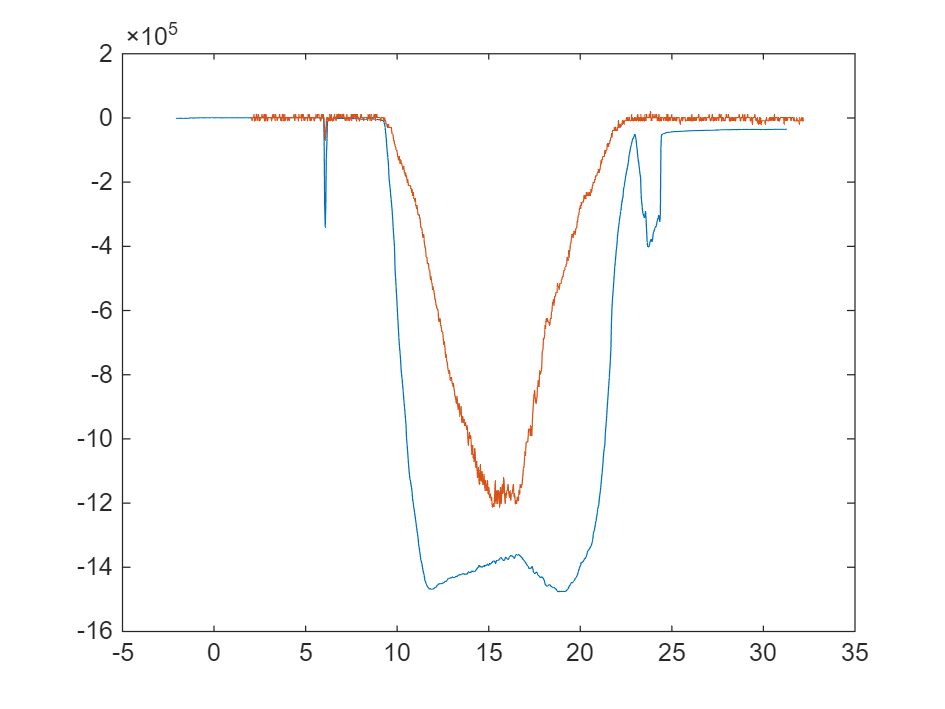

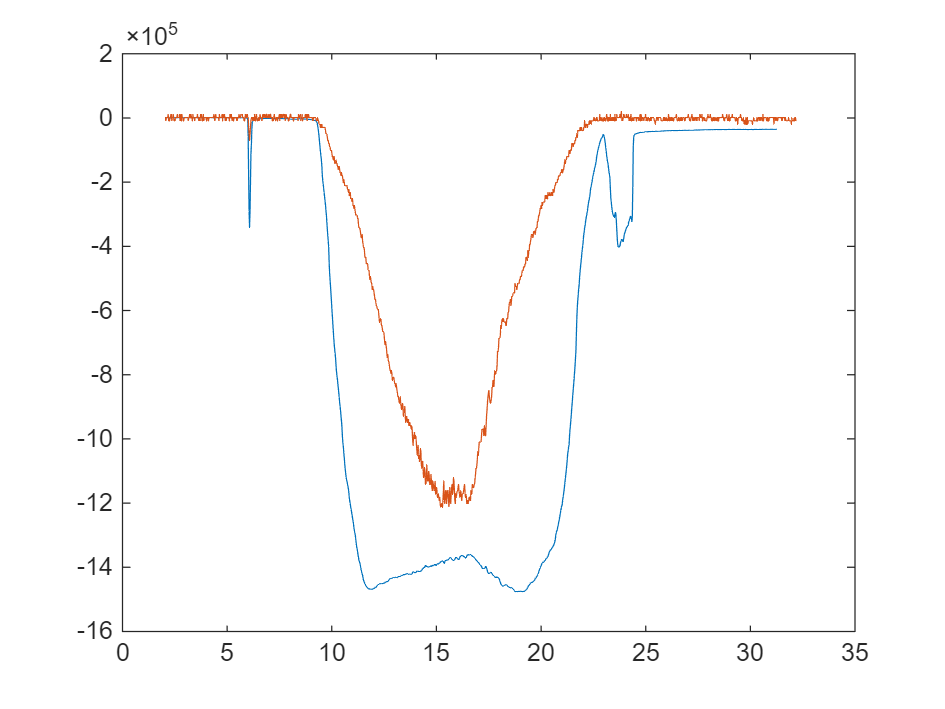

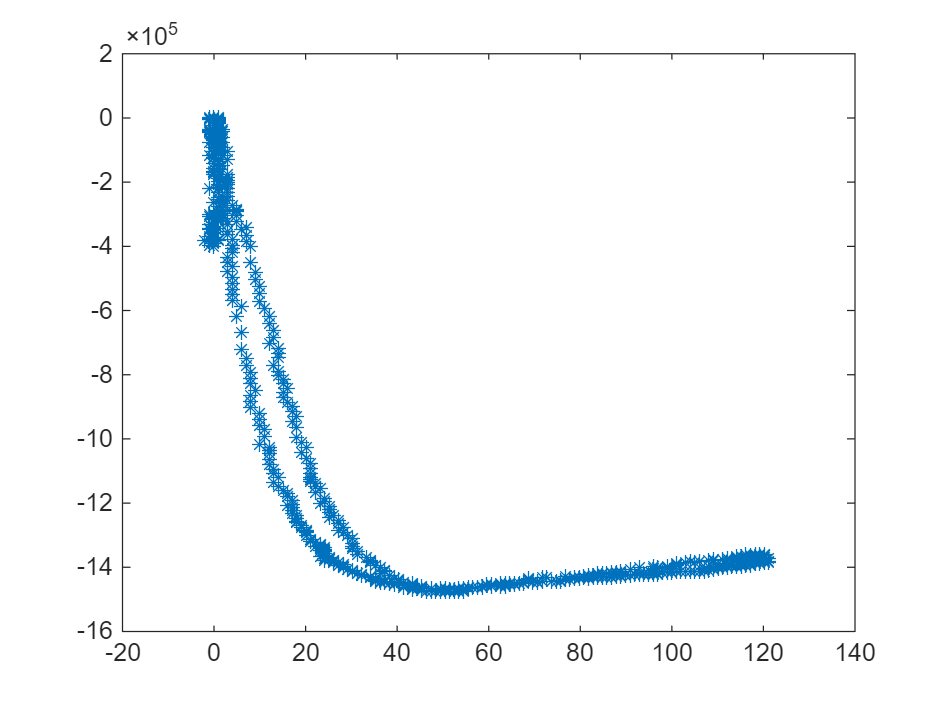

max_force = 51.4591

addpath("force_plate");
addpath("sensor");

data2plot = cell(1,3);
max_index = zeros(1,3);

for i = 1:3

    diff = [2339, 1955, 2203] ./1000;

    fp_name = strcat('fp_',num2str(i),'.txt');
    ss_name = strcat('ss_',num2str(i),'.txt');

    plate_data = readmatrix(fp_name,"Delimiter",",", 'Whitespace',' N');
    plate_data(end,:) = [];
    sensor_data = readmatrix(ss_name);
    sensor_data(end,:) = [];

    % fp_1: 7885 = ss_1: 10224  ---- diff = 2339
    % fp_2: 5569 = ss_2: 7524   ---- diff = 1955
    % fp_3: 6071 = ss_3: 8274   ---- diff = 2203

    baseline_plate_mag = mean(plate_data(1:100,2))

    plate_time = plate_data(:,1)./1000;
    plate_mag = plate_data(:,2) - baseline_plate_mag;
    sensor_time = sensor_data(:,1)./1000-diff(i);
    sensor_mag = sensor_data(:,2) - mean(sensor_data(1:100,2));

    adj_plate_mag = plate_mag * (-10000);

    figure;
    plot(sensor_time,sensor_mag);
    hold on
    plot(plate_time,adj_plate_mag);
    hold off

    sensor_mag_interp = interp1(sensor_time,sensor_mag,plate_time);

    figure;
    plot(plate_time,sensor_mag_interp);
    hold on
    plot(plate_time,adj_plate_mag);
    hold off

    abs_plate_mag = adj_plate_mag ./ (-10000);

    figure;
    plot(abs_plate_mag,sensor_mag_interp,'*')
    
    data2save = [abs_plate_mag,sensor_mag_interp];
    data2plot{i} = data2save;
    [min_sensor,min_ind] = min(sensor_mag_interp);
    max_force = abs_plate_mag(min_ind)
    max_index(i) = min_ind;

end

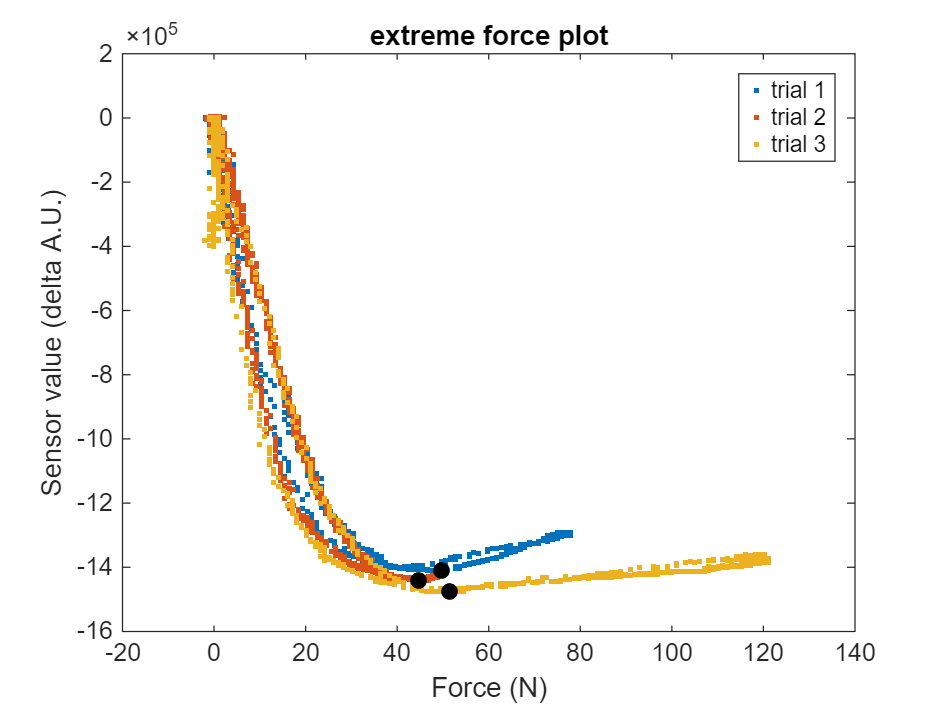


figure;
plot(data2plot{1}(:,1),data2plot{1}(:,2),'.')
hold on
plot(data2plot{2}(:,1),data2plot{2}(:,2),'.')
plot(data2plot{3}(:,1),data2plot{3}(:,2),'.')
plot(data2plot{1}(max_index(1),1),data2plot{1}(max_index(1),2),'k.','MarkerSize',20)
plot(data2plot{2}(max_index(2),1),data2plot{2}(max_index(2),2),'k.','MarkerSize',20)
plot(data2plot{3}(max_index(3),1),data2plot{3}(max_index(3),2),'k.','MarkerSize',20)
hold off
legend('trial 1','trial 2','trial 3')
title('extreme force plot')
xlabel('Force (N)')
ylabel('Sensor value (delta A.U.)')